# **Vectores y Matrices**

**Vectores**

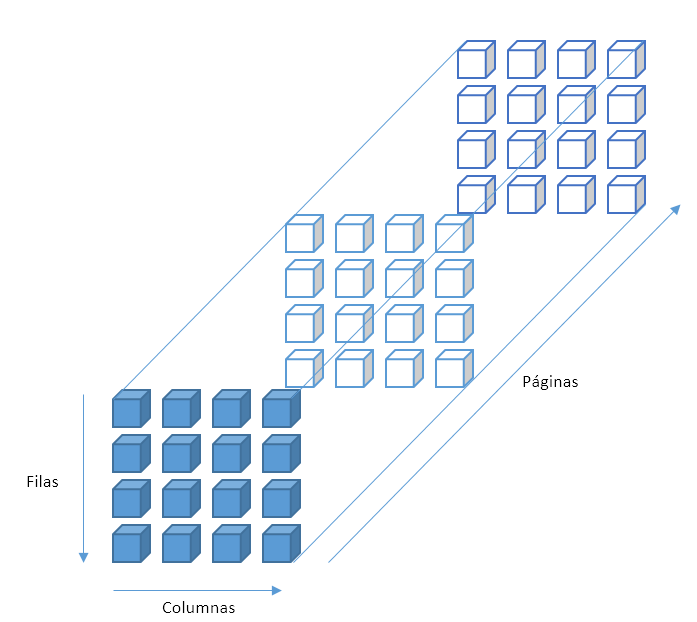

## Introducción

MATLAB está diseñado para trabajar eficientemente con vectores (*arrays*), matrices y otros arreglos de datos. 

Las matrices y arrays son arreglos de datos del mismo tipo. Tanto las matrices como los arrays se crean en general utilizando los corchetes [ ], aunque, como veremos más adelante, también existen funciones que crean vectores y matrices de especial utilidad. 

La diferencia entre ambos es que los arrays son arreglos de una única dimensión mientras que las matrices son de dos o más dimensiones. 

## Básico

help plot

plot - 2-D line plot

    This MATLAB function creates a 2-D line plot of the data in Y versus the
    corresponding values in X.

    plot(X,Y)
    plot(X,Y,LineSpec)
    plot(X1,Y1,...,Xn,Yn)
    plot(X1,Y1,LineSpec1,...,Xn,Yn,LineSpecn)
    plot(Y)
    plot(Y,LineSpec)
    plot(___,Name,Value)
    plot(ax,___)
    h = plot(___)

    See also <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/gca.html">gca</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/hold.html">hold</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/legend.html">legend</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/loglog.html">loglog</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/plot3.html">plot3</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/title.html">title</a>, <a href="https://www.mathworks.com/help/releases/R2020b/matlab/ref/xlabel.html">xlabel</a>, <a href="https://www.ma

a=8

a =      8


3+5

ans =      8


ans*2;
Num=10

Num =     10


numero2=45

numero2 =     45


str='Hola Mundo'

str = 'Hola Mundo'

b=Num+numero2    

b =     55


curva = 2*pi

curva =     10


pi = 5;
curva = 2*pi

curva =     10


vect=[1 2 3 4 5 6 7]

vect =      1     2     3     4     5     6     7


vectcol=[2;4;5;7;-1;0]

vectcol =      2
     4
     5
     7
    -1
     0


## Vector fila

Los vectores fila son arreglos de datos en los que la longitud de la primera dimensión es 1.

Para crear un vector fila podemos introducir los valores entre corchetes y separados por comas.  

a=[1, 2, 5, 9]

a =      1     2     5     9


a0 = zeros(1,10)

a0 =      0     0     0     0     0     0     0     0     0     0


a1 = ones(1,10)

a1 =      1     1     1     1     1     1     1     1     1     1


Es posible omitir las comas.

a2=[5 9 0 12]

a2 =      5     9     0    12


a3=[5745 12325 -6.8678]

a3 =                       5745                     12325                   -6.8678



%vectores de caracteres
a4=[1 'dos' 3 'cuatro' 5]

a4 = 'doscuatro'

a4(1)+a4(3)

ans =    112


str2double(a4(1))+str2double(a4(3))

ans =    NaN


Podemos saber la longitud de cualquier vector o matriz utilizando los comandos *length* o *size*.

El comando *length* devuelve la longitud de la primera dimensión mayor a 1 de un vector o matriz. El comando *size* devuelve el tamaño de todas las dimensiones si no se especifica la dimensión.

longitud=length(a2)

longitud =      4



[filas,columnas]=size(a2)

filas =      1


columnas =      4



filas=size(a2,1)

filas =      1


columnas=size(a2,2)

columnas =      4


También podemos ver en cualquier momento las dimensiones de los arreglos en la pestaña del *workspace* si se marca esta opción de visualización y mediante el comando *whos.*

whos

  Name                     Size              Bytes  Class     Attributes

  A                        3x3                  72  double              
  A1                       3x3                  72  double              
  A2                       3x3                 144  double    complex   
  A3                       3x3                  72  double              
  A4                       2x2                  32  double              
  B                        3x1                  24  double              
  B1                       3x3                  72  double              
  B2                       1x5                  40  double              
  B3                       7x7                 392  double              
  B4                       5x5                 200  double              
  B5                       3x3                  72  double              
  B6                       6x6                 288  double              
  B_canal                  1x2                  16

Para acceder a los elementos de los arrays utilizaremos los paréntesis de la siguiente forma. Los índices en MATLAB empiezan en 1. 

a3(3)       % Accedemos al tercer elemento del array a3

ans =                    -6.8678


a3(2)

ans =        12325


a3(2)+a3(3) % Podemos hacer operaciones directamente accediendo a los elementos de los arrays

ans =                 12318.1322


Se puede definir un array o matriz indicando directamente la posición de los elementos.

a4(2)=35

a4 = '#oscuatro'

Observad que en este caso hemos indicado que el segundo elemento del array a4 debe valer 35. Como no hemos especificado el primer elemento del arreglo MATLAB automáticamente le asignará un valor 0. Completemos la definición del array.

a4(3)=26, a4(4)=32, a4(1)=5

a4 = '#scuatro'

a4 = '# cuatro'

a4 = '# cuatro'

Observad que cuando definimos un vector en MATLAB, éste aumenta su tamaño cuando es necesario. Sin embargo, cuando se intenta acceder a un elemento que excede las dimensiones del array, MATLAB nos mostrará un mensaje de error.

#### Ejercicio 1

Cree un vector fila de longitud 8 con los primeros números primos: 

numeros_primos = [2, 3, 5, 7, 11, 13, 17, 19]

numeros_primos =      2     3     5     7    11    13    17    19


El operador : permite crear series numéricas.

Podemos crear una serie numérica de la siguiente forma:

 ini=0

ini =      0


 paso=5 

paso =      5


 fin=100

fin =    100


 serie=ini:paso:fin

serie =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100


 serie2=1:20

serie2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


Si no se especifica el paso, éste tiene como valor por defecto 1.

#### Ejercicio 2

Cree un vector columna cuyos elementos estén comprendidos entre 15 y 150 con un paso 5. Utilice los dos puntos " : " para crear los elementos del vector. Compruebe el tamaño del vector.

vector_columna = transpose([15:5:150]);
longitud       = size(vector_columna);
tamano_vector  = longitud(1)

tamano_vector =     28


## Vector columna

En los vectores columna la dimensión 2 tiene un valor de 1. Los elementos se separan por " ; "

b=[12;56;21;17]

b =     12
    56
    21
    17


size(b)

ans =      4     1


El apóstrofe, ' , transpone un vector o matriz y puede resultar útil en ocasiones para crear vectores columna a partir de vectores fila.

b2=[15 67 23 68]'

b2 =     15
    67
    23
    68


b3=a2'

b3 =      5
     9
     0
    12


Es posible concatenar vectores para crear arrays de mayores dimensiones.

X=1:5       % Vectores fila

X =      1     2     3     4     5


Y=10:-1:6

Y =     10     9     8     7     6


conc=[X Y]  % Concatenación horizontal

conc =      1     2     3     4     5    10     9     8     7     6


X2=X'

X2 =      1
     2
     3
     4
     5


Y2=Y'

Y2 =     10
     9
     8
     7
     6


conc2=[X2;Y2]

conc2 =      1
     2
     3
     4
     5
    10
     9
     8
     7
     6


## Matrices

Las matrices se crean de igual forma que los *arrays *pero definiendo los elementos de las filas y columnas. Una matriz debe tener el mismo número de elementos en todas las filas y columnas.

A=[20 99 43;  45 27 77; 81 9 -3]    % Se crea una matriz de 3 filas y 3 columnas

A =     20    99    43
    45    27    77
    81     9    -3


size(A)

ans =      3     3


Se pueden definir cada una de las posiciones exactamente como en el caso de los arrays indicando la posición de cada una de las dimensiones.

A(2,1)=25       % Asignamos al elemento de la segunda fila y primera columna el valor 25

A =     20    99    43
    25    27    77
    81     9    -3


A(2,2)=5+7      

A =     20    99    43
    25    12    77
    81     9    -3




A(2)=0          % Es conveniente definir las posiciones de todas las dimensiones De lo contrario MATLAB 

A =     20    99    43
     0    12    77
    81     9    -3


                % interpretará que es el orden del elemento cogiendo en
                % primer lugar las columnas

A(5)

ans =     12


Para acceder a un subconjunto de los valores de una matriz se utilizan los dos puntos :

A(1,:)          % Devuelve todos los elementos de la primera fila

ans =     20    99    43


A(:,2)          % Devuelve todos los elementos de la segunda columna

ans =     99
    12
     9


A(1:2,1)        % Devuleve los dos primeros elementos de la primera columna

ans =     20
     0


La palabra clave *end* permite indicar el último elemento de una dimensión.

Las matrices pueden tener más de dos dimensiones. Esto es de especial utilidad cuando se trabaja con imágenes o videos.

A2(1,1,1)=1, A2(2,2,1)=1, A2(3,3,1)=1, A2(2,1,2)=5       % Creamos una matriz de 3 x 3 x 2

A2 =                           1 +                     0i                          8 +                     0i                          0 +                     0i
                          1 +                     0i                          2 -                     1i                          0 +                     0i
                         -7 +                     0i                          3 +                     0i                          0 +                     4i


A2 =                           1 +                     0i                          8 +                     0i                          0 +                     0i
                          1 +                     0i                          1 +                     0i                          0 +                     0i
                         -7 +                     0i                          3 +                     0i                          0 +                     4i


A2 =      1     8     0
     1     1     0
    -7     3     1


A2 = A2(:,:,1) =

     1     8     0
     1     1     0
    -7     3     1


A2(:,:,2) =

     0     0     0
     5     0     0
     0     0     0


size(A2)

ans =      3     3     2


A2(:,:,3)=[1 1 1; 1 1 1; 1 1 1]

A2 = A2(:,:,1) =

     1     8     0
     1     1     0
    -7     3     1


A2(:,:,2) =

     0     0     0
     5     0     0
     0     0     0


A2(:,:,3) =

     1     1     1
     1     1     1
     1     1     1


size(A2)

ans =      3     3     3


## Otras formas de crear vectores y matrices

Existen funciones que nos facilitan la labor de crear matrices y arrays. 

Un ejemplo de este tipo de funciones son *linspace*, *ones, zeros, eye o rand*, entre otras.

La función *linspace* es una función de gran utilidad que permite crear un vector de una longitud determinada cuyos elementos están equiespaciados entre el valor inferior y el superior.

b4=linspace(0,1,1001)   % Crea un array entre 0 y 1, incluidos, con 10001 puntos

b4 =                          0                     0.001                     0.002                     0.003                     0.004                     0.005                     0.006                     0.007                     0.008                     0.009                      0.01                     0.011                     0.012                     0.013                     0.014                     0.015                     0.016                     0.017                     0.018                     0.019                      0.02                     0.021                     0.022                     0.023                     0.024                     0.025                     0.026                     0.027                     0.028                     0.029                      0.03                     0.031                     0.032                     0.033                     0.034                     0.035                     0.036                     0.037       

Busque la ayuda sobre las funciones *ones, zeros, eye *y* diag* y observe el resultado obtenido con las siguientres instrucciones.

B=ones(4,3)       % Creamos una matriz de 4 x 3 cuyos elementos son 1.

B =      1     1     1
     1     1     1
     1     1     1
     1     1     1


B2=2*ones(1,5)

B2 =      2     2     2     2     2


B3=2+ones(7)      % Si solo se especifica un valor MATLAB lo interpreta como una matriz cuadrada

B3 =      3     3     3     3     3     3     3
     3     3     3     3     3     3     3
     3     3     3     3     3     3     3
     3     3     3     3     3     3     3
     3     3     3     3     3     3     3
     3     3     3     3     3     3     3
     3     3     3     3     3     3     3



B4=zeros(5),B4(5,3)=6

B4 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


B4 =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     6     0     0



B5=eye(3)         % Matriz identidad

B5 =      1     0     0
     0     1     0
     0     0     1


B6=rand(6)

B6 =          0.641098001884061         0.479354672278283         0.950278455856644          0.93285257903537        0.0665450272277532         0.062067323435421
         0.909235816079593        0.0241193910089731          0.22597629759182          0.82331610236868         0.434433339419399         0.888213544253344
         0.146333689670365         0.743499900338366         0.409757526736672         0.827386654375193         0.803358337870702          0.55130249520221
         0.686000932186153         0.182525732067909         0.123821463172728         0.952079092396327          0.70979203968121         0.770555644233174
         0.389811931160742         0.882110262238475         0.469675170762487         0.309546142142196          0.58668851184352          0.21009939740521
         0.338741162187972         0.790526771407065          0.44454658427274        0.0273226502380352         0.431561974280031        0.0327102220050407


#### Ejercicio 3

Dividir el intervalo [0,$\pi$] en 100 intervalos iguales.

division_intervalo = linspace(0,pi)

division_intervalo =                          0        0.0505050505050505         0.101010101010101         0.151515151515152         0.202020202020202         0.252525252525253         0.303030303030303         0.353535353535354         0.404040404040404         0.454545454545455         0.505050505050505         0.555555555555556         0.606060606060606         0.656565656565657         0.707070707070707         0.757575757575758         0.808080808080808         0.858585858585859         0.909090909090909          0.95959595959596          1.01010101010101          1.06060606060606          1.11111111111111          1.16161616161616          1.21212121212121          1.26262626262626          1.31313131313131          1.36363636363636          1.41414141414141          1.46464646464646          1.51515151515152          1.56565656565657          1.61616161616162          1.66666666666667          1.71717171717172          1.76767676767677          1.81818181818182          1.86868

#### Ejercicio 4

Cree una matriz de 4x4 elementos cuyos elementos de la diagonal principal sean igual a 2. Los restantes elementos serán valores distintos entre sí, escogidos a voluntad. Utilice como mínimo alguna de las siguientes funciones: *diag, eye, ones, zeros, tril *o* triu.*


matriz = reshape(randsample([3:20],4^2),[4 4]);

matriz =      3    12    14     1
     0     4    19     8
    16    18     7    13
     5     6    11     9


matriz(eye(size(matriz))==1) = 2

matriz =      2    12    14     1
     0     2    19     8
    16    18     2    13
     5     6    11     2


## Operaciones con vectores y matrices

En las operaciones con vectores y matrices se debe tener en cuenta si se éstas operaciones se producen con un escalar o con otra matriz o vector.

### Suma y resta

Cuando se realiza la suma (o resta) entre un escalar y una matriz (o vector), el escalar se suma a todos los elementos. 

A=[1 3 5; 5 6 -1; 0 3 2]

A =      1     3     5
     5     6    -1
     0     3     2


A+2

ans =      3     5     7
     7     8     1
     2     5     4


Si la operación se produce entre dos matrices, éstas deben ser del mismo tamaño y se realiza elemento a elemento.

B=[6 -1 0; 9 0.3 -1; 1/8 1 1]

B =                          6                        -1                         0
                         9                       0.3                        -1
                     0.125                         1                         1


A2=A+B

A2 =                          7                         2                         5
                        14                       6.3                        -2
                     0.125                         4                         3


### Multiplicación

La multiplicación por un escalar se produce elemento a elemento.

En caso de una multiplicación entre dos matrices tenemos dos opciones. 

- La multiplicación de matrices. Tened en cuenta que el número de columnas de la primera matriz debe ser igual al número de filas de la segunda matriz.

M=A*B

M =                     33.625                       4.9                         2
                    83.875                      -4.2                        -7
                     27.25                       2.9                        -1


        2. Multiplicar elemento a elemento, utilizando el operador " .* "

M2=A.*B

M2 =                          6                        -3                         0
                        45                       1.8                         1
                         0                         3                         2


### División

Al igual que en el caso de la multiplicación la operación con un escalar se realiza sobre todos los elementos de la matriz o vector.

En el caso de dos matrices es posible realizar la operación elemento a elemento utilizando el operador " ./ ".

Utiliar el operador " / " equivale a $A/B=A*B^{-1}$, es decir, multiplicar por la derecha con la matriz inversa. 

Si utilizamos el operador " \ " equivale a $A\backslash B=A^{-1} *B$. Vamos a comprobar que es así:

Div=A/B

Div = 3×3
          1.10709010339734         -0.68685376661743          4.31314623338257
         -3.38035450516987          2.78434268833087          1.78434268833087
         -0.55834564254062           0.3397341211226           2.3397341211226


B1=inv(B)

B1 = 3×3
        0.0768094534711965        0.0590841949778434        0.0590841949778434
        -0.539143279172821         0.354505169867061         0.354505169867061
         0.529542097488922        -0.361890694239291         0.638109305760709


A*B1

ans = 3×3
          1.10709010339734         -0.68685376661743          4.31314623338257
         -3.38035450516987          2.78434268833087          1.78434268833087
         -0.55834564254062           0.3397341211226           2.3397341211226



Divl=A\B

Divl = 3×3
                   2.78125                    -0.755                      -0.7
        -0.645833333333333                      0.61                       0.4
                   1.03125                    -0.415                      -0.1


A1=inv(A)

A1 = 3×3
                      0.25                      0.15                     -0.55
        -0.166666666666667        0.0333333333333333         0.433333333333333
                      0.25                     -0.05                     -0.15


A1*B

ans = 3×3
                   2.78125                    -0.755                      -0.7
        -0.645833333333333                      0.61                       0.4
                   1.03125                    -0.415                      -0.1


### Transposición

Mediante la transposición intercambiamos las filas y las columnas. Esto se realiza mediante el uso del apóstrofe " ' ".

En caso de matrices de números complejos este operador realiza la transposición conjugada. Para no realizar la conjugada utilizaremos el operador " .' "

A2=[3+2i 8 0; 1 2-1i 0; -7 3 4i]

A2 = 3×3
                          3 +                     2i                          8 +                     0i                          0 +                     0i
                          1 +                     0i                          2 -                     1i                          0 +                     0i
                         -7 +                     0i                          3 +                     0i                          0 +                     4i


A2'

ans = 3×3
                          3 -                     2i                          1 +                     0i                         -7 +                     0i
                          8 +                     0i                          2 +                     1i                          3 +                     0i
                          0 +                     0i                          0 +                     0i                          0 -                     4i


### Potenciación

El operador " ^ " para exponentes enteros mayores a 1 equivale a multiplicar la matriz o vector tantas veces como indica el exponente. Recuerde que por lo general la potencia de una matriz será posible calcularla cuando se trate de matrices cuadradas.

Usando el punto delante del operador realizaremos la operación elemento a elemento, " .^ ".

A3=A^2

A3 = 3×3
    16    36    12
    35    48    17
    15    24     1


### Autovalores y autovectores

Al multiplicar un vector por una matriz, el resultado por lo general es un vector con una magnitud y dirección distintas a las del vector original. Se puede interpretar una matriz como una función que convierte un vector en otro vector y de este modo transforma el espacio original. Puede darse que algunos vectores del espacio original mantengan la dirección en el nuevo espacio. A estos vectores se les llama autovectores. Se llama autovalor al factor que modifica la norma (longitud) de estos vectores durante la transformación. El cálculo de autovalores y autovectores es común en muchos campos de la ingeniería y nos puede proporciona información muy importante sobre estas transformaciones. 

Formalmente se debe cumplir que $A\upsilon =\lambda \upsilon$, con $\upsilon \not= 0$, siendo $A$ una matriz, $\upsilon$ un autovector y $\lambda$ un autovalor.

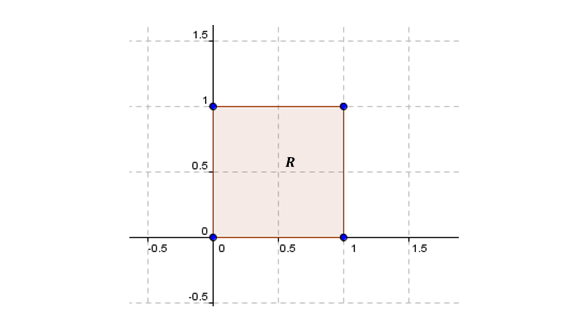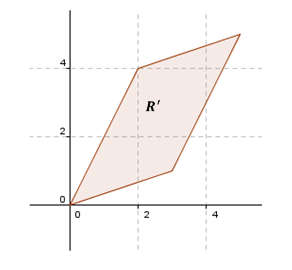

Para el cálculo de los autovalores utilizaremos la función *eig*.

A4=[3 2; 1 4]

A4 = 2×2
     3     2
     1     4


[V,D]=eig(A4)

V = 2×2
        -0.894427190999916        -0.707106781186547
         0.447213595499958        -0.707106781186548


D = 2×2
     2     0
     0     5


#### Ejercicio 5

Resolver en forma matricial ([A^-1][A]·[X]=[A^-1][B]) el siguiente sistema de ecuaciones:

Calcule el rango de la matriz, el determinante y los autovalores y autovectores. Utilice las funciones *rank *y* det.*


A = [1, 3, -5;-1, 1 3;2, 2, 1];
B = [4;6;-10];


Parte_1 = 3×3
                         1     -1.11022302462516e-16                         0
                         0                         1      2.22044604925031e-16
                         0                         0                         1


Parte_2 = 3×1
         -6.61111111111111
          2.05555555555556
        -0.888888888888889


X = inv(inv(A)*A)*(inv(A)*B)

X = 3×1
         -6.61111111111111
          2.05555555555556
        -0.888888888888889



rango_A        = rank(A)

rango_A =      3


determinante_A = det(A)

determinante_A =     36


## Ejercicios adicionales

**Introducción a MATLAB**

[https://matlabacademy.mathworks.com/R2020a/es/portal.html?course=gettingstarted](https://matlabacademy.mathworks.com/R2020a/es/portal.html?course=gettingstarted)